# 2-dof Parameters used in Simulink models

This script defines the model parameters that are used in the following Simulink and Simscape example models:

$\bullet \quad$bh_2dof_ODE_model.slx       

$\bullet \quad$bh_2dof_simscape_model.slx  

$\bullet \quad$bh_2dof_compare_models.slx  

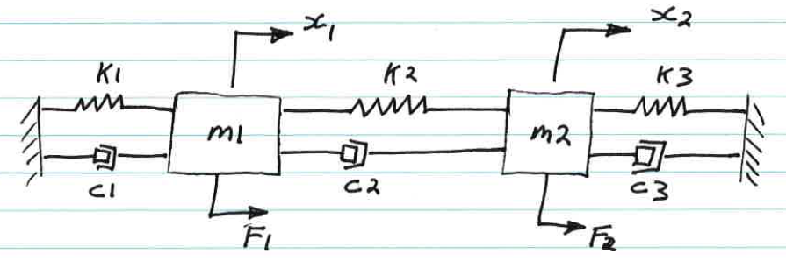

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

## Define the Mass, Damping and Spring constants:

% The mechanical parameters
params = bh_func_2dof_params();

m1 = params.m1 ;    m2 = params.m2 ; 
k1 = params.k1 ;    k2 = params.k2 ;    k3 = params.k3 ;
c1 = params.c1 ;    c2 = params.c2 ;    c3 = params.c3 ;

So the system co-efficient matrices are:

$\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$. \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$ + $\pmatrix{
(c_1 + c_2) & -c_2 \cr
-c_2 & (c_2+c_3) \cr
}$$. \pmatrix{
\dot{x}_1 \cr
\dot{x}_2 \cr
}$ + $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & (k_2+k_3) \cr
}$$. \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{F}_1 \cr
{F}_2 \cr
}$

which we can refer to as:   

- $M \ddot{X} + C\dot{X} + KX = F$   where   $X \in R^{2\times1}$

Mm_mat  = [m1,    0;
            0,   m2  ];

Km_mat  = [ (k1+k2), -k2;
            -k2,     (k2+k3) ];

Cm_mat  = [ (c1+c2),  -c2;
            -c2,      (c2+c3) ];

## Define the Initial conditions:

The initial conditions (ICs) of the system also need to be defined:

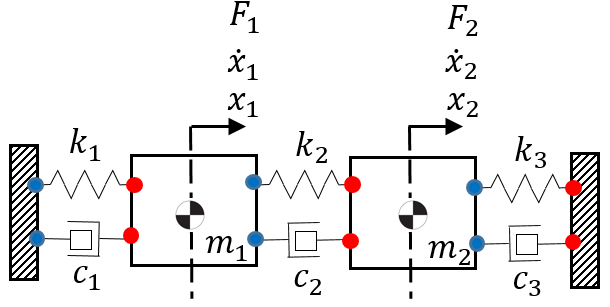   

These initial conditions are:

- ${\dot{x} }_1 \left(0\right)=\text{ }\text{ }\text{ }\text{ }0$,          $x_1 \left(0\right)=\text{ }\text{ }\text{ }1\text{ }$

- ${\dot{x} }_2 \left(0\right)=\text{ }\text{ }\text{ }\text{ }5$,          $x_2 \left(0\right)=-0\ldotp 5$ 

init_x1dot = 0;    init_x1    =  1;
init_x2dot = 5;    init_x2    = -0.5;

## SIMULINK:  define initial states

In vector form we can write the system's initial conditions as: (note the vector order is $\left\lbrack x_1 ,{\text{ }\text{ }\text{ }x}_2 \right\rbrack$)

init_pos_col = [init_x1;    init_x2   ];
init_vel_col = [init_x1dot; init_x2dot];

If we model this system in Simulink, then these INITIAL CONDITIONS get assigned to the integrator blocks (ie: $\frac{1}{s}$).  The initial conditions are the initial state values coming our of each integrator block.  Conceptually  it looks like this:

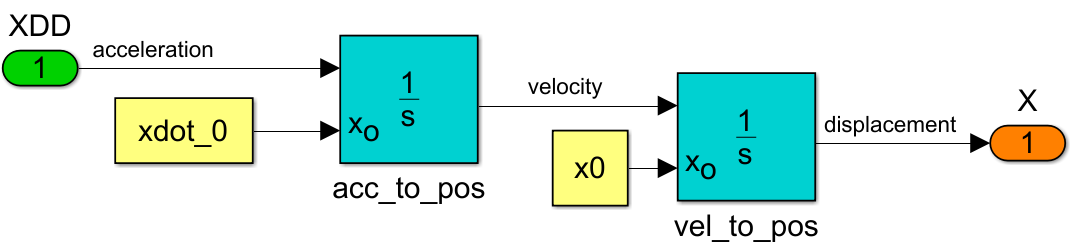

## SIMSCAPE:  define initial spring deformations

If we were to model this same  system in Simscape, then we initialise the model by defining the initial **spring deformations** $\Delta$ and the initial **velocities of the masses**  The Simscape spring block uses the following convention:

   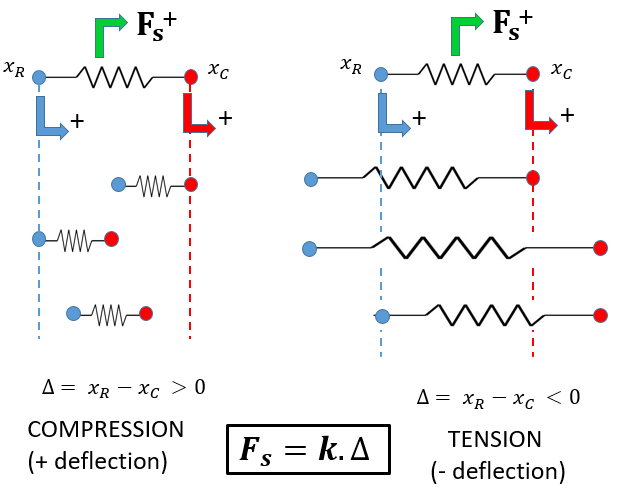

Note, when we construct the Simscape model, we'll assemble the model "vertically, ie:

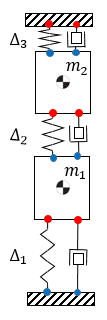, so let's define some parameters that we can use to configure each of the springs and masses:

## Spring 1 and Mass 1:

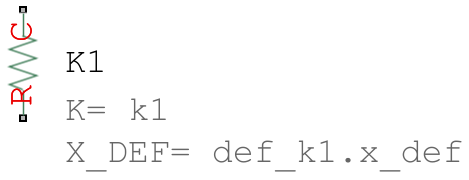   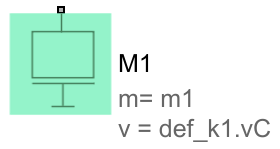

def_k1       = [];
def_k1.xR    = 0;             def_k1.vR    = 0;
def_k1.xC    = init_x1;       def_k1.vC    = init_x1dot;

def_k1.x_def = def_k1.xR  - def_k1.xC;    % delta = xR - xC 

## Spring 2 and Mass 2:

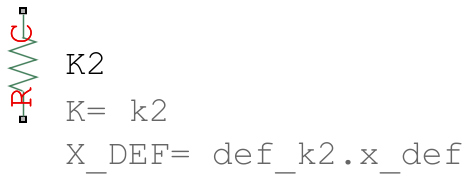   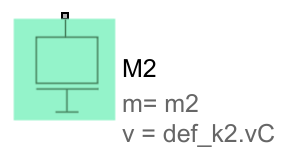

def_k2       = [];
def_k2.xR    = init_x1;       def_k2.vR    = init_x1dot;
def_k2.xC    = init_x2;       def_k2.vC    = init_x2dot;

def_k2.x_def = def_k2.xR - def_k2.xC;     % delta = xR - xC 

## Spring 3:

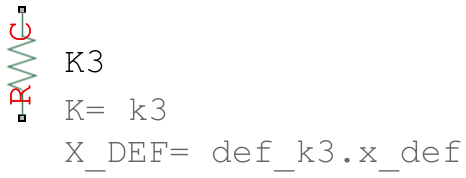 

def_k3       = [];
def_k3.xR    = init_x2;       def_k3.vR    = init_x2dot;
def_k3.xC    = 0;             def_k3.vC    = 0;

def_k3.x_def = def_k3.xR - def_k3.xC;     % delta = xR - xC 

One final comment on using Simscape:  When we use the  "**Ideal Motion Translation Motion Sensor**" to measure the position and velocity of a mass, we need to configure the initial position value of the mass being read.  For example for $m_2$ we would configure the block as: